# Least Squares Template Matching

- used for artifact removal

- need to separate eye movements from the eeg data

### Load the dataset

load templateProjection.mat;
whos;

  Name            Size                Bytes  Class     Attributes

  EEGdat       1500x707             4242000  single              
  eyedat       1500x707             4242000  single              
  npnts           1x1                     8  double              
  timevec         1x1500              12000  double              



### Plot a sample 

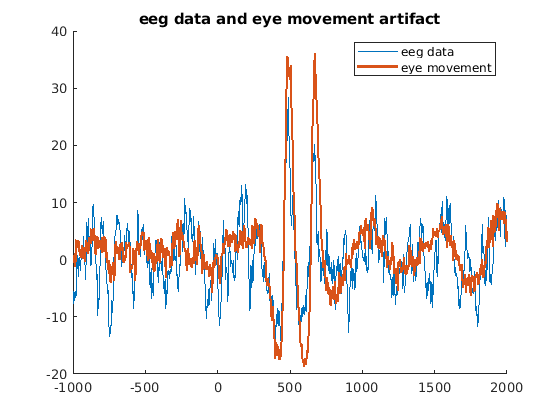

figure(1); clf;
hold on;
eeg_plot = plot(timevec, EEGdat(:,1));
eye_plot = plot(timevec,eyedat(:,1), 'linew', 2);
title("eeg data and eye movement artifact");
legend({"eeg data", "eye movement"});
hold off;

### Calculate Least Squares

- [https://medium.com/@andrew.chamberlain/the-linear-algebra-view-of-least-squares-regression-f67044b7f39b](https://medium.com/@andrew.chamberlain/the-linear-algebra-view-of-least-squares-regression-f67044b7f39b) 

residuals = zeros(size(EEGdat));

for i=1:size(residuals,2)
    X = [ones(npnts,1) eyedat(:,i)];
    %\ operator is inverse
    beta = (X'*X) \ (X'*EEGdat(:,i));
    y_hat = X*beta;
    residuals(:,i) = (EEGdat(:,i) - y_hat)';
end

### Plot the results

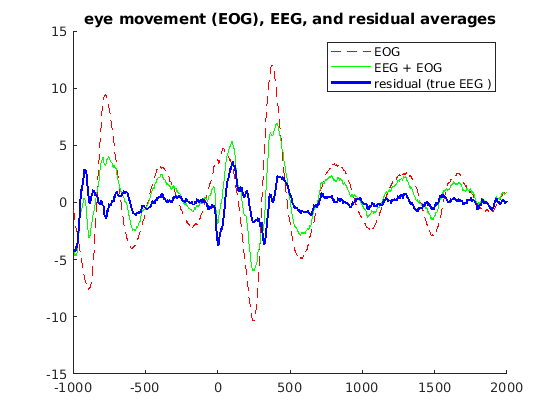

figure (2); clf;
hold on;
eyeMu_plot = plot(timevec, mean(eyedat,2), '--r');
eegMu_plot = plot(timevec, mean(EEGdat, 2), 'g');
res_plot = plot(timevec, mean(residuals,2), 'b', 'linew', 2);
title("eye movement (EOG), EEG, and residual averages");
legend({"EOG", "EEG + EOG", "residual (true EEG )"});
hold off;

### Show trials in a color plot

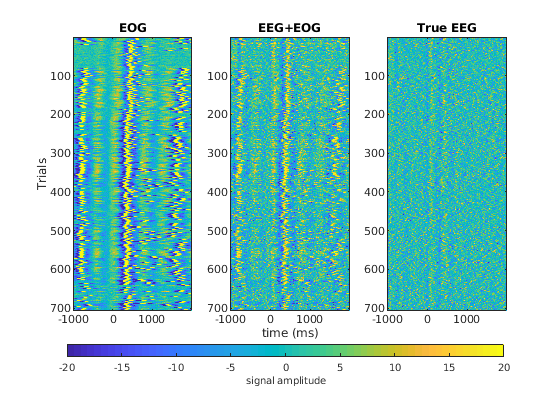

lim = [-20 20];

figure(3); clf;
ax(1) = subplot(131);
imagesc(timevec,[],eyedat');
set(gca, 'clim',lim);
ylabel("Trials");
title("EOG");

ax(2) = subplot(132);
imagesc(timevec,[], EEGdat');
set(gca, 'clim',lim);
xlabel("time (ms)");
title("EEG+EOG");

ax(3) = subplot(133);
imagesc(timevec,[], residuals');
set(gca, 'clim', lim);
title("True EEG");

c = colorbar('southoutside', 'Position', [0.12 .15 .78 .03]);
c.Label.String = "signal amplitude";
%adjust size of subplot
for i=1:3
    plt = get(ax(i), 'Position');
    set(ax(i), 'Position', [plt(1) plt(2)+.15 plt(3) .8*plt(4)]);
end